# Radiation Heat Transfer: Heat Exchange Between Nonblackbodies

By: [Shayan Moghaddam](https://www.linkedin.com/in/shayan-moghaddam-b3804b1bb/) (smoghad@ncsu.edu, shayanmgh79@gmail.com)

## The Problem Description

Let's examine a three-dimensional object as depicted in Figure 1. This object consists of three distinct surfaces (These values are sample and can be changed based on the problem):

- The upper disk, referred to as Surface 1, has a radius of 0.6 meters and is maintained at a temperature of 500 K. It possesses an emissivity of 0.7.

- The lower disk, designated as Surface 2, also has a radius of 0.6 meters but is heated to a temperature of 650 K. Its emissivity is 0.5.

- The side area, referred to as Surface 3, has an emissivity of 0.4 and a length of 1.2 m, but its temperature remains unknown.

Additionally, there is a heat flow of 1400 W entering from the lower disk. Our goal is to calculate the temperature of Surface 3 and determine the heat exchange between Surface 1 and Surface 2, as well as between Surface 2 and Surface 3.

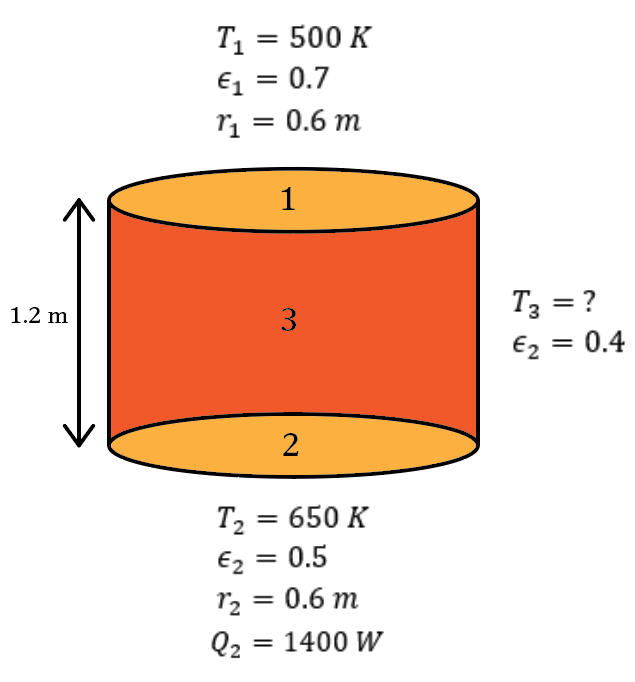

Figure 1. Schematic View of the Described 3D Object

## Step-by-Step Solution

### 1. Radiation Network

First, in order to have a better understanding of the problem, we should draw the radiation network of the system (Figure 2).

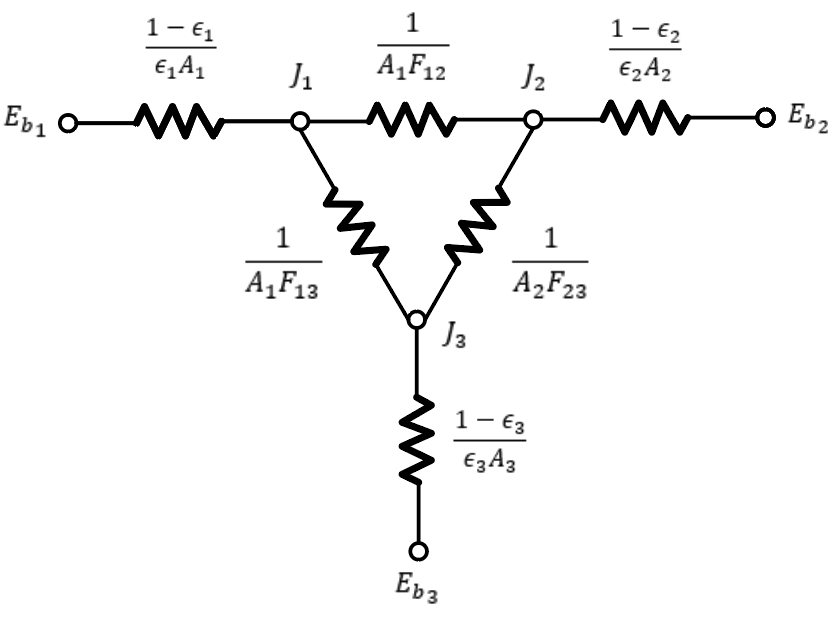

Figure 2. Radiation Network of the three surfaces.

In Figure 2, $E_{b_n }$is the blackbody emissive power of the surface n, and $J_n$ is the radiosity of surface n (Total radiation that leaves a surface per unit time and per unit area). The radiation resistances between the surfaces and in a surface, are demonstrated in figure 2. 

### 2. Defining The Constants, Finding The Shape-Factors

Now we can start the coding. Let's define the constants first:

clear, clc;

% All constants are sample and can be changed based on the problem.
r1 = 0.6;                 % Upper disk diameter (m)
r2 = 0.6;                 % Lower disk diameter (m)
L = 1.2;                  % Length of the cylinder (m)
epsilon_1 = 0.7;          % Upper disk emissivity
epsilon_2 = 0.5;          % Lower disk emissivity
epsilon_3 = 0.4;          % cylinder inner body emissivity
T1 = 500;                 % Upper disk temperature (K)
T2 = 650;                 % Lower disk temperature (K)
sigma = 5.67 * 10^(-8);   % Stefan-Boltzmann Constant (W/(m^2.K^4))
Q2 = 1400;                % Heat transfer to the lower disk (W)

The radiation shape-factor relations are shown in the table 8-2 (Holman). $F_{12}$ can be calculated by the fifth equation, since we have two coaxial disks:

% According to the Table 8-2 (Holman), for parallel coaxial disks:
R1 = r1/L;   R2 = r2/L;   X = 1 + (1+R2^2)/R2^2;
F12 = (X-(X^2-4*(R2/R1)^2)^0.5)/2;

The other shape-factors now can be calculated:


$$\begin{array}{l}
F_{11} +F_{12} +F_{13} =1\\
F_{21} +F_{22} +F_{23} =1\\
F_{11} =F_{22} =0\\
F_{12} =F_{21} 
\end{array}$$


% Calculating other shape-factors:
F11 = 0;
F22 = 0;
F13 = 1 - (F12 + F11);
F21 = F12;
F23 = 1 - (F21 + F22);

### 3. Radiation Heat Resistance, $E_{b_1 }$, $E_{b_2 }$ and $J_2$ Calculations

Radiation Heat Resistances which are mentioned in the figure 2, can be calculated as follows:

Res_1 = ( 1-epsilon_1 )/( pi*r1^2*epsilon_1 );  % Upper disk
Res_2 = ( 1-epsilon_2 )/( pi*r2^2*epsilon_2 );  % Lower disk
Res_3 = ( 1-epsilon_3 )/( 2*pi*(r1+r2)/2*L*epsilon_3 );  % Inner surface area
Res_12 = 1/( pi*r1^2*F12 );
Res_13 = 1/( pi*r1^2*F13 );
Res_23 = 1/( pi*r2^2*F23 );

Since we have $T_1 \;$and $T_2$, $E_{b_1 }$and $E_{b_2 }$can be calculated:

Eb1 = sigma * T1^4;   Eb2 = sigma * T2^4;

For the node 2, we have:


$$Q_2 =\frac{\left(E_{b_2 } -J_2 \right)}{\frac{\left(1-\epsilon {\;}_2 \right)}{A_2 \epsilon {\;}_2 }}$$


So $J_2 \;$can be calculated:

J2 = Eb2 - Q2 * Res_2;

### 4. Energy Balance and System of Linear Equations Solving

#### 4-1. Energy Balance

In this section, we derive the system of equations by writing the heat balances and solve the system of linear equations by various numerical methods. You can find the details of each method in the ["System of Linear Equations" Folder](https://github.com/SinaGhanbarii/Numerical-Methods-and-Their-Application-in-Chemical-Engineering/tree/main/System%20of%20Linear%20Equations).

The heat balance for each node can be written as follows:


$$\begin{array}{l}
\textrm{node}\;1:\frac{\left(E_{b_{1\;} } -J_1 \right)}{\frac{\left(1-\epsilon {\;}_1 \right)}{A_1 \epsilon {\;}_1 }}+\frac{\left(J_2 -J_1 \right)}{\frac{1}{A_1 F_{12} }}+\frac{\left(J_3 -J_1 \right)}{\frac{1}{A_1 F_{13} }}=0\\
\textrm{node}\;2:\frac{\left(E_{b_2 } -J_2 \right)}{\frac{\left(1-\epsilon {\;}_2 \right)}{A_2 \epsilon {\;}_2 }}+\frac{\left(J_1 -J_2 \right)}{\frac{1}{A_1 F_{12} }}+\frac{\left(J_3 -J_2 \right)}{\frac{1}{A_2 F_{23} }}=0\\
\textrm{node}\;3:\frac{\left(E_{b_3 } -J_3 \right)}{\frac{\left(1-\epsilon {\;}_3 \right)}{A_3 \epsilon {\;}_3 }}+\frac{\left(J_1 -J_3 \right)}{\frac{1}{A_1 F_{13} }}+\frac{\left(J_2 -J_3 \right)}{\frac{1}{A_2 F_{23} }}=0
\end{array}$$


By rewriting the equations we have:


$$\begin{array}{l}
\textrm{node}\;1:\left(-\frac{1}{\frac{\left(1-\epsilon {\;}_1 \right)}{A_1 \epsilon {\;}_1 }}-\frac{1}{\frac{1}{A_1 F_{12} }}-\frac{1}{\frac{1}{A_1 F_{13} }}\right)\;{\times \;J}_1 +\left(\frac{1}{\frac{1}{A_1 F_{13} }}\right){\times \;J}_3 =-\frac{E_{b_2 } }{\frac{\left(1-\epsilon {\;}_1 \right)}{A_1 \epsilon {\;}_1 }}-\frac{J_2 }{\frac{1}{A_1 F_{12} }}\\
\textrm{node}\;2:\left(\frac{1}{\frac{1}{A_1 F_{12} }}\right){\times \;J}_1 +\left(\frac{1}{\frac{1}{A_2 F_{23} }}\right){\times \;J}_3 =-\frac{E_{b_2 } }{\frac{\left(1-\epsilon {\;}_2 \right)}{A_2 \epsilon_2 }}+\left(\frac{1}{\frac{\left(1-\epsilon {\;}_2 \right)}{A_2 \epsilon {\;}_2 }}+\frac{1}{\frac{1}{A_1 F_{12} }}+\frac{1}{\frac{1}{A_2 F_{23} }}\right)\;{\times \;J}_2 \\
\textrm{node}\;3:\left(\frac{1}{\frac{1}{A_1 F_{13} }}\right){\times \;J}_1 +\left(-\frac{1}{\frac{\left(1-\epsilon {\;}_3 \right)}{A_3 \epsilon {\;}_3 }}-\frac{1}{\frac{1}{A_1 F_{13} }}-\frac{1}{\frac{1}{A_2 F_{23} }}\right)\;{\times \;J}_3 +\frac{E_{b_3 } }{\frac{\left(1-\epsilon {\;}_3 \right)}{A_3 \epsilon {\;}_3 }}=-\frac{J_2 }{\frac{1}{A_2 F_{23} }}\\

\end{array}$$


we have a system of linear equations that can be shown in the form of coefficients and constants matrices:


$$\left\lbrack \begin{array}{ccc}
\left(-\frac{1}{\frac{\left(1-\epsilon {\;}_1 \right)}{A_1 \epsilon {\;}_1 }}-\frac{1}{\frac{1}{A_1 F_{12} }}-\frac{1}{\frac{1}{A_1 F_{13} }}\right) & \left(\frac{1}{\frac{1}{A_1 F_{13} }}\right) & 0\\
\left(\frac{1}{\frac{1}{A_1 F_{12} }}\right) & \left(\frac{1}{\frac{1}{A_2 F_{23} }}\right) & 0\\
\left(\frac{1}{\frac{1}{A_1 F_{13} }}\right) & \left(-\frac{1}{\frac{\left(1-\epsilon {\;}_3 \right)}{A_3 \epsilon {\;}_3 }}-\frac{1}{\frac{1}{A_1 F_{13} }}-\frac{1}{\frac{1}{A_2 F_{23} }}\right) & \left(\frac{1}{\frac{\left(1-\epsilon {\;}_3 \right)}{A_3 \epsilon {\;}_3 }}\right)
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
J_1 \\
J_3 \\
E_{b_3 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\frac{E_{b_2 } }{\frac{\left(1-\epsilon {\;}_1 \right)}{A_1 \epsilon {\;}_1 }}-\frac{J_2 }{\frac{1}{A_1 F_{12} }}\\
-\frac{E_{b_2 } }{\frac{\left(1-\epsilon {\;}_2 \right)}{A_2 \epsilon_2 }}+\left(\frac{1}{\frac{\left(1-\epsilon {\;}_2 \right)}{A_2 \epsilon {\;}_2 }}+\frac{1}{\frac{1}{A_1 F_{12} }}+\frac{1}{\frac{1}{A_2 F_{23} }}\right)\;{\times \;J}_2 \\
-\frac{J_2 }{\frac{1}{A_2 F_{23} }}
\end{array}\right\rbrack$$


#### 4-2. Solving The System of Equations by Regular Method

% regular solving

Coefficients_Matrix = [ (-1/Res_1) + (-1/Res_12) + (-1/Res_13),  (1/Res_13),  0;
    (1/Res_12),  (1/Res_23),  0;
    (1/Res_13),  (-1/Res_3) + (-1/Res_13) + (-1/Res_23),  (1/Res_3)];

Constants_Matrix = [ (-Eb1/Res_1) + (-J2/Res_12);
    (-Eb2/Res_2) + (J2/Res_2) + (J2/Res_12) + (J2/Res_23);
    (-J2/Res_23)];

Regular_Answers = Coefficients_Matrix \ Constants_Matrix;
J1_regular = Regular_Answers (1);
J3_regular = Regular_Answers (2);
Eb3_regular = Regular_Answers (3);

T3_regular = (Eb3_regular/sigma)^0.25;
Q12_regular = (J2 -J1_regular)/Res_12;
Q23_regular = (J2 -J3_regular)/Res_23;

fprintf("Regular T3:"), disp(T3_regular);

Regular T3:  630.9704



fprintf("Regular Q12:"), disp(Q12_regular);

Regular Q12:  758.3230



fprintf("Regular Q23:"), disp(Q23_regular);

Regular Q23:  641.6770



fprintf("------------------------------\n")

------------------------------


#### 4-3. Solving The System of Equations by Gauss-Seidel Method

S = [1; 1; 1];  % Initial Guess - This is a sample. You can change it later!
Gauss_Seidel_Answers = ones(length(Constants_Matrix), 1);  % Initialize x as a column vector
Iter_num = 30;
omega = 1;      %Relaxation factor
for m = 1:Iter_num
    for i = 1:length(Constants_Matrix)
        % Calculate the sum of products (excluding diagonal element)
        total_sum = Coefficients_Matrix(i, :) * Gauss_Seidel_Answers - Coefficients_Matrix(i, i) * Gauss_Seidel_Answers(i);

        % Update the solution vector component x(i) with relaxation factor
        Gauss_Seidel_Answers(i) = (1 - omega) * Gauss_Seidel_Answers(i) + (omega / Coefficients_Matrix(i, i)) * (Constants_Matrix(i) - total_sum);
    end
end

J1_Gauss_Seidel = Gauss_Seidel_Answers (1);
J3_Gauss_Seidel = Gauss_Seidel_Answers (2);
Eb3_Gauss_Seidel = Gauss_Seidel_Answers (3);

T3_Gauss_Seidel = (Eb3_Gauss_Seidel/sigma)^0.25;
Q12_Gauss_Seidel = (J2 -J1_Gauss_Seidel)/Res_12;
Q23_Gauss_Seidel = (J2 -J3_Gauss_Seidel)/Res_23;

fprintf("Gauss-Seidel T3:"), disp(T3_Gauss_Seidel);

Gauss-Seidel T3:  630.9704



fprintf("Gauss-Seidel Q12:"), disp(Q12_Gauss_Seidel);

Gauss-Seidel Q12:  758.3230



fprintf("Gauss-Seidel Q23:"), disp(Q23_Gauss_Seidel);

Gauss-Seidel Q23:  641.6770



fprintf("------------------------------\n")

------------------------------


#### 4-4. Solving The System of Equations by Gauss-Jordan Method

n = length(Coefficients_Matrix);
Gauss_Jordan_Answers = zeros(n,1);
for i=1:n-1
    if Coefficients_Matrix(i,i)==0
        [m, k]=max(abs(Coefficients_Matrix(i+1:end,i)));
        Coefficients_Matrix(i,:)=Coefficients_Matrix(i,:)+Coefficients_Matrix(i+k,:);
        Constants_Matrix(i)=Constants_Matrix(i)+Constants_Matrix(i+k);
    end
end
M=[Coefficients_Matrix,Constants_Matrix];

for j=1:n-1
    for i=j+1:n
        M(i,:)=M(i,:)-M(j,:)*(M(i,j)/M(j,j));
    end
end

for j=1:n-1
    for i=j+1:n
        M(i,:)=M(i,:)-M(j,:)*(M(i,j)/M(j,j));
    end
end

for j=n:-1:2
    for  i=j-1:-1:1
        M(i,:)=M(i,:)-M(j,:)*(M(i,j)/M(j,j));
    end
end

for i=1:n
    M(i,:)=M(i,:)/M(i,i);
    Gauss_Jordan_Answers(i)=M(i,n+1);
end

J1_Gauss_Jordan = Gauss_Jordan_Answers (1);
J3_Gauss_Jordan = Gauss_Jordan_Answers (2);
Eb3_Gauss_Jordan = Gauss_Jordan_Answers (3);

T3_Gauss_Jordan = (Eb3_Gauss_Jordan/sigma)^0.25;
Q12_Gauss_Jordan = (J2 -J1_Gauss_Jordan)/Res_12;
Q23_Gauss_Jordan = (J2 -J3_Gauss_Jordan)/Res_23;

fprintf("Gauss-Jordan T3:"), disp(T3_Gauss_Jordan);

Gauss-Jordan T3:  630.9704



fprintf("Gauss-Jordan Q12:"), disp(Q12_Gauss_Jordan);

Gauss-Jordan Q12:  758.3230



fprintf("Gauss-Jordan Q23:"), disp(Q23_Gauss_Jordan);

Gauss-Jordan Q23:  641.6770



fprintf("------------------------------\n");

------------------------------


#### 4-5. Solving The System of Equations by Gaussian Elimination Method

C=[Coefficients_Matrix Constants_Matrix];

n=length(Constants_Matrix);
Gaussian_Elimination_Answers=zeros(n,1);

for i=1:n-1
    if Coefficients_Matrix(i,i)==0
        [m, k]=max(abs(A(i+1:end,i)));
        Coefficients_Matrix(i,:)=Coefficients_Matrix(i,:)+Coefficients_Matrix(i+k,:);
        Constants_Matrix(i)=Constants_Matrix(i)+Constants_Matrix(i+k);
    end
end

for k=1:n-1
    for i=k+1:n
        s=Coefficients_Matrix(i,k)/Coefficients_Matrix(k,k);
        for j=k+1:n
            Coefficients_Matrix(i,j)=Coefficients_Matrix(i,j)-s*Coefficients_Matrix(k,j);
        end
        Constants_Matrix(i)=Constants_Matrix(i)-s*Constants_Matrix(k);
    end
end

Gaussian_Elimination_Answers(n)=Constants_Matrix(n)/Coefficients_Matrix(n,n);
for i=n-1:-1:1
    r=0;
    for j=i+1:n
        r=r+Coefficients_Matrix(i,j)*Gaussian_Elimination_Answers(j);
        Gaussian_Elimination_Answers(i)=(Constants_Matrix(i)-r)/Coefficients_Matrix(i,i);
    end
end
for i=1:n
    for j=1:n
        if (j<i) Coefficients_Matrix(i,j)=0; end
    end
end

J1_Gaussian_Elimination = Gaussian_Elimination_Answers (1);
J3_Gaussian_Elimination = Gaussian_Elimination_Answers (2);
Eb3_Gaussian_Elimination = Gaussian_Elimination_Answers (3);

T3_Gaussian_Elimination = (Eb3_Gaussian_Elimination/sigma)^0.25;
Q12_Gaussian_Elimination = (J2 -J1_Gaussian_Elimination)/Res_12;
Q23_Gaussian_Elimination = (J2 -J3_Gaussian_Elimination)/Res_23;

fprintf("Gaussian Elimination T3:"), disp(T3_Gaussian_Elimination);

Gaussian Elimination T3:  630.9704



fprintf("Gaussian Elimination Q12:"), disp(Q12_Gaussian_Elimination);

Gaussian Elimination Q12:  758.3230



fprintf("Gaussian Elimination Q23:"), disp(Q23_Gaussian_Elimination);

Gaussian Elimination Q23:  641.6770



fprintf("------------------------------\n")

------------------------------


#### 4-6. Solving The System of Equations by LU Decomposition Method

A = Coefficients_Matrix;
b = Constants_Matrix;
C=[A b];

n = length(b);
LU_Decomposition_Answers = zeros(n,1);
d = zeros(n,1);

for i=1:n-1
    if A(i,i)==0
        [m,k]=max(abs(A(i+1:end,i)));
        A(i,:)=A(i,:)+A(i+k,:);
        b(i)=b(i)+b(i+k);
    end
end

L(1,1)=A(1,1);
for i=1:n
    U(i,i)=1;
end

for j=2:n
    L(j,1)=A(j,1);
    U(1,j)=A(1,j)/A(1,1);
end

for i=2:n-1
    S=0;
    for k=1:i-1
        S=S+U(k,i)*L(i,k);
    end
    L(i,i)=(A(i,i)-S)/U(i,i);
    for j=i+1:n
        S=0;
        for k=1:i-1
            S=S+U(k,i)*L(j,k);
        end
        L(j,i)=(A(j,i)-S)/U(i,i);
        S=0;
        for k=1:i-1
            S=S+U(k,j)*L(i,k);
        end
        U(i,j)=(A(i,j)-S)/L(i,i);
    end
end

S=0;
for k=1:n-1
    S=S+U(k,n)*L(n,k);
end
L(n,n)=(A(n,n)-S)/U(n,n);

d(1)=b(1)/L(1,1);
for i=2:n
    t=0;
    for k=1:i-1
        t=t+L(i,k)*d(k);
    end
    d(i)=(b(i)-t)/L(i,i);
end

LU_Decomposition_Answers(n)=d(n);
for j=n-1:-1:1
    r=0;
    for k=j+1:n
        r=r+U(j,k)*LU_Decomposition_Answers(k);
    end
    LU_Decomposition_Answers(j)=d(j)-r;
end

J1_LU_Decomposition = LU_Decomposition_Answers (1);
J3_LU_Decomposition = LU_Decomposition_Answers (2);
Eb3_LU_Decomposition = LU_Decomposition_Answers (3);

T3_LU_Decomposition = (Eb3_LU_Decomposition/sigma)^0.25;
Q12_LU_Decomposition = (J2 -J1_LU_Decomposition)/Res_12;
Q23_LU_Decomposition = (J2 -J3_LU_Decomposition)/Res_23;

fprintf("LU Decomposition T3:"), disp(T3_LU_Decomposition);

LU Decomposition T3:  630.9704



fprintf("LU Decomposition Q12:"), disp(Q12_LU_Decomposition);

LU Decomposition Q12:  758.3230



fprintf("LU Decomposition Q23:"), disp(Q23_LU_Decomposition);

LU Decomposition Q23:  641.6770



fprintf("------------------------------\n")

------------------------------


#### 4-7. Solving The System of Equations by Thomas Method

A = Coefficients_Matrix;
C = Constants_Matrix;
n=length(C);
Thomas_Answers=zeros(n,1);

%we'll save A & C matrices intact and do the pivoting on another matrix
LU=A;   %matrix to pivot
C_LU=C; %matrix to pivot

for k=1:n
    if A(k,k)==0
        [LU,C_LU]=pivot(LU,C_LU);
    end
end     %partial pivoting for main diameter

%Part A: decomposition for
%the first column and the lower diameter
%no need to modify the A or LU matrix

%Part B----partial pivoting for main diameter
for k=1:n
    if LU(k,k)==0
        [LU,C_LU]=pivot(LU,C_LU);
    end
end

%Part C----decomposition for the main and upper diameters:
%gamma(j)=U(j,j+1)=LU(j,j+1) for: j=1:n-1
%therefore we have to substract j from 1
for j=2:n
    LU(j-1,j)=LU(j-1,j)/LU(j-1,j-1); %for gamma(j-1) j=2:n
    LU(j,j)=LU(j,j)- LU(j,j-1)* LU(j-1,j); %for beta(j) j=2:n
end
%------------------------

%Part A: forward subtitution (LD=C):
D=Thomas_Answers;
D(1)=C_LU(1)/LU(1,1); %for the first d (  d(1) )

for k=2:n
    sum=0;
    for m=1:k-1
        sum=sum+D(m)*LU(k,m);
    end

    D(k)=(C_LU(k)-sum) /LU(k,k);
end

%Part B:back subtitution (UX=D):
Thomas_Answers(n)=D(n); %for the last x (xn)

for k=n-1:-1:1
    sum=0;
    for m=n:-1:k+1
        sum=sum+Thomas_Answers(m)*LU(k,m);
    end

    Thomas_Answers(k)=D(k)-sum;
end

J1_Thomas = Thomas_Answers (1);
J3_Thomas = Thomas_Answers (2);
Eb3_Thomas = Thomas_Answers (3);

T3_Thomas = (Eb3_Thomas/sigma)^0.25;
Q12_Thomas = (J2 -J1_Thomas)/Res_12;
Q23_Thomas = (J2 -J3_Thomas)/Res_23;

fprintf("Thomas T3:"), disp(T3_Thomas);

Thomas T3:  630.9704



fprintf("Thomas Q12:"), disp(Q12_Thomas);

Thomas Q12:  758.3230



fprintf("Thomas Q23:"), disp(Q23_Thomas);

Thomas Q23:  641.6770



And there you have it, The solution is complete!